## global body planner test

addpath(genpath('body_traj_planner'));
x_init = [0;0;0; 0;0;0.3];
vel_tar = [0;0;0.05; 1;0;0];
horizon_num = 200;
dt = 0.05;
[state_traj] = body_traj_planner(x_init ,vel_tar, horizon_num, dt)

state_traj =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

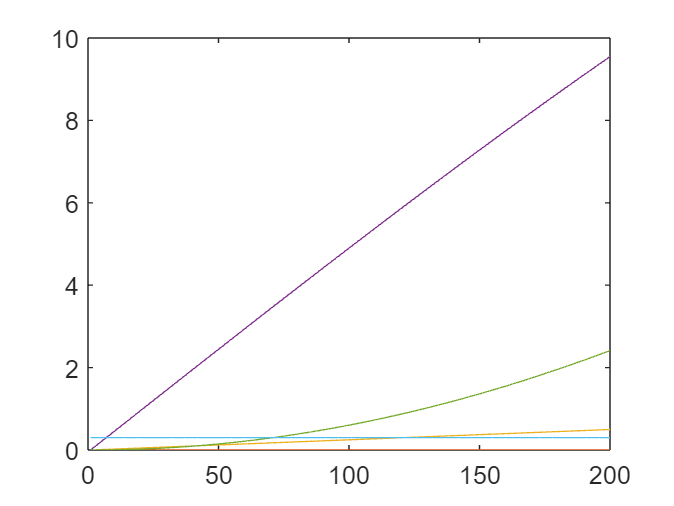


for i=1:6
plot(state_traj(i,:))
hold on
end

## local swing foot planner test

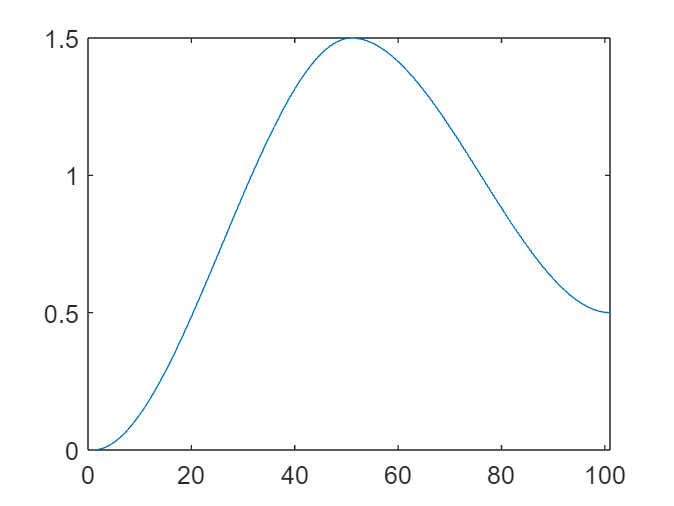

addpath(genpath('body_traj_planner'));
p_start = [-1;-1;0];
p_end = [1;1;0.5];
fp_h = 1.5;
fpp_arr = [];

for t_sw = 0:0.01:1
    fpp_t = swing_fpp_planner(p_start,p_end,fp_h,t_sw);
    fpp_arr = [fpp_arr, fpp_t];
end

clf;
plot(fpp_arr(3,:));